clearvars; close all; clc;

# Dependent property mspl (Maximum SPL)

2024-07-07, JVsound, J.G. Vermond

## Introduction

The mspl property of the acoustics.simulation class calculates the maximum sound pressure level (SPL) in [dB], at radius $r$ or at the microphone position for imported FEA results.

The SPL is limited by the properties:

- xlim: maximum cone excursion [m]

- plim: maximum power [W]

These are properties of the acoustics.simulation class, and are not to be mistaken for the xmax and paes properties of the speaker.woofer class.

## Theory

The sound pressure level in [dB] is calculated as follows:


$$SPL = 20\log_{10}\left(\frac{p_{rms}}{p_{ref}}\right)$$


At very low frequencies where the diaphragm has not yet become a direction radiator (i.e. its circumference is less than about a wavelength), the loudspeaker be treated as though it were a simple spherical source of sound. The sound pressure in the free field is calculated by:


$$p(r) = -jf\rho_0U_c\frac{e^{-jkr}}{2r}$$


For a plane circular piston in an infinite baffle the sound pressure [Pa] in the far-field is calculated by:


$$p(r) = -jf\rho_0U_c\frac{e^{-jkr}}{r}$$


If $U_c$ is rms volume velocity, the resulting pressure $p$ is the rms pressure. $f$ is substituted with $\omega/(2\pi)$:


$$p(r) = -j\omega\rho_0U_c\frac{e^{-jkr}}{2\pi r}$$


The variables $j\omega U_c$ tell us that the sound pressure is proportional to diaphragm acceleration. See also the following example:


$$y(t) = e^{j\omega t}$$



$$\frac{dy}{dt} = j \omega e^{j\omega t}$$


$e^{-jkr}$ is a part of the function, which is frequency (and radius) dependent, but does not change the amplitude of the function of $p$.

## Calculation

The following calculations assume a well setup simulation object, which generates required output from the dependent property sim2port. To complex electric power from the generator is output $S_g$. For other calculations the generator voltage $e_g$ and resulting current $i_g$ are also available:

The complex electric power $S_g%$ is calculated by:


$$S = VI^*$$


## Output

## Example

### Setting up simulation

Create a woofer:

% Create woofer object
wf			= speaker.woofer;

wf.brand	= "B&C";
wf.model	= "18SW115-8";
wf.size		= 18;

wf.re		= 5.3;
wf.qes		= .32;
wf.qms		= 5.6;
wf.fs		= 32;
wf.sd		= 1210e-4;
wf.vas		= 187e-3;

wf.le		= 1.9e-3;
wf.xmax		= 14e-3;
wf.paes		= 1700

wf =   woofer with properties:

    brand: "B&C"
    model: "18SW115-8"
     size: 18
       re: 5.3000
      qes: 0.3200
      qms: 5.6000
       fs: 32
       sd: 0.1210
      vas: 0.1870
       le: 0.0019
     xmax: 0.0140
     paes: 1700
      qts: 0.3027
      cms: 9.1045e-05
      kms: 1.0984e+04
      mms: 0.2717
      mmd: 0.2241
      rms: 9.7550
       bl: 30.0795
        a: 0.1963


Create a closed box object:

% Closed box:
cb			= enclosure.closedbox(150e-3);

Create a simulation object and add closed box and woofer:

% Simulation object:
sim1		= acoustics.simulation;

sim1.sp		= wf;
sim1.encl	= cb;

### Voltage, current and power

Although the outputs from the dependent properties of the simulation class are a function of frequency, the following figures show the sinusoidal behaviour over time for a single frequency. This to get a better insight in the relation between complex voltage, current and power.

The frequency to show: $f$

% Create copy of simulation object for single frequency:
sim2 		= sim1;
sim2.f 		= 1e2;

% Period of frequency:
T 			= 1 / sim2.f;

% Time array:
t 			= linspace(0,T,1e2);

#### Voltage

The RMS voltage of the generator (amplifier) is $e_g$, which is a property of the simulation object:

eg 		= sim2.eg

eg = 2.8300


% Complex function over time:
egt 	= abs(eg) * exp(1i*sim2.w.*t);

We plot the voltage over time.

fig1 				= figure;
ax1 				= axes(fig1); hold on; grid on;
ax1.FontSize 		= 8;
ax1.XLabel.String 	= "[s]";
ax1.Title.String 	= "Voltage and current over time";

yyaxis left
plot(ax1,t,real(egt),LineWidth=1.5);
plot(ax1,t,imag(egt),LineWidth=1.5);

#### Current

The current $i_g$ is an output of the sim2port dependent property:

% Complex current:
ig		= sim2.sim2port.ig;

% Complex function over time:
igt 	= abs(ig) * exp(1i*sim2.w.*t + 1i*angle(ig));

The current is plotted in the same figure as the voltage:

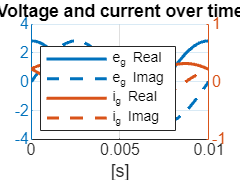

yyaxis right
plot(ax1,t,real(igt),LineWidth=1.5);
plot(ax1,t,imag(igt),LineWidth=1.5);

ax1.YAxis(2).Limits 	= [-1 1];

leg1 			= legend(ax1,"e_g Real","e_g Imag","i_g Real","i_g Imag");
leg1.Location 	= "southwest";

#### Power

Time domain:

The instantenuous power is calculated by multiplying $e_g$ and $i_g$.


$$e_g(t) = E\cos(\omega t + \phi_e)$$



$$i_g(t) = I\cos(\omega t + \phi_i)$$



$$P_{inst}(t) = e_g(t)i_g(t)$$



$$P_{inst}(t) = EI\cos(\omega t + \phi_e)\cos(\omega t + \phi_i)$$


Using the trigonomic identity $\cos(\alpha)\cos(\beta) = \frac{1}{2}[\cos(\alpha+\beta)+\cos(\alpha-\beta)]$ we can write $P_{inst}(t)$ as:


$$P_{inst}(t) = \frac{1}{2}EI\cos(\phi_e-\phi_i) + \frac{1}{2} EI \cos(2\omega t + \phi_v + \phi_i)$$


The 2nd term can be rewritten to:


$$\frac{1}{2}EI\cos(2\omega t + \phi_v + \phi_i) = \frac{1}{2}EI\cos(2\omega t + 2\phi_i + \phi_v - \phi_i) $$


Then using the identity $\cos(\alpha \pm \beta) = \cos(\alpha)\cos(\beta)\mp \sin(\alpha)\sin(\beta)$:


$$\frac{1}{2}EI\cos(2\omega t + 2\phi_i + \phi_v - \phi_i) = \frac{1}{2}EI\cos(\phi_e-\phi_i)\cos(2\omega t + 2\phi_i) - \frac{1}{2} EI\sin(\phi_e - \phi_i)\sin(2\omega t + 2\phi_i)$$


Substitution in the $P_{inst}(t)$ function:


$$P_{inst}(t) = \frac{1}{2}EI\cos(\phi_e-\phi_i) +  \frac{1}{2}EI\cos(\phi_e-\phi_i)\cos(2\omega t + 2\phi_i) - \frac{1}{2} EI\sin(\phi_e - \phi_i)\sin(2\omega t + 2\phi_i)$$



$$P_{inst}(t) = P + P\cos(2\omega t + 2\phi_i) - Q\sin(2\omega t + 2\phi_i)$$


The average power is the mean of the instantenuous power: $P_{ave}$

% Instantenuous power:
Pinst 		= real(egt) .* real(igt);
% Average power:
Pave 		= mean(Pinst) * ones(size(Pinst));
% Alternating power:
Palt 		= Pinst - Pave;

The complex power $S_g$ in the time domain can be calculated by multiplying the voltage and current functions in exponential format:


$$e_g = Ee^{(j\omega t + j\phi_v)}$$



$$i_g = Ie^{(j\omega t + j\phi_i)}$$



$$S_g = e_gi_g^*$$



$$S_g = Ee^{(j\omega t+j\phi_v)} Ie^{(j\omega t-j\phi_i)}$$


which can be rewritten to:


$$S_g = EIe^{(j\phi_v-j\phi_i)}e^{(j2\omega t)}$$


Challenge: the power function over time must have a positive (or negative) real offset. This function $S_g$ does not have that ... 

% Complex power:
Sgt		= abs(eg)*abs(ig)*exp(1i*(angle(eg)-angle(ig)))*exp(1i*2*sim2.w*t)

Sgt =    0.6136 - 0.6497i   0.6909 - 0.5668i   0.7571 - 0.4748i   0.8111 - 0.3751i   0.8521 - 0.2694i   0.8793 - 0.1594i   0.8924 - 0.0468i   0.8912 + 0.0666i   0.8756 + 0.1789i   0.8459 + 0.2883i   0.8026 + 0.3930i   0.7464 + 0.4915i   0.6781 + 0.5820i   0.5990 + 0.6632i   0.5102 + 0.7337i   0.4133 + 0.7923i   0.3096 + 0.8383i   0.2010 + 0.8707i   0.0892 + 0.8892i  -0.0241 + 0.8933i  -0.1370 + 0.8831i  -0.2477 + 0.8586i  -0.3544 + 0.8204i  -0.4554 + 0.7689i  -0.5491 + 0.7051i  -0.6339 + 0.6299i  -0.7085 + 0.5446i  -0.7718 + 0.4505i  -0.8226 + 0.3492i  -0.8602 + 0.2422i  -0.8839 + 0.1314i  -0.8935 + 0.0184i  -0.8886 - 0.0948i  -0.8694 - 0.2065i  -0.8363 - 0.3149i  -0.7897 - 0.4183i  -0.7304 - 0.5149i  -0.6593 - 0.6032i  -0.5777 - 0.6818i  -0.4867 - 0.7495i  -0.3879 - 0.8051i  -0.2829 - 0.8477i  -0.1733 - 0.8767i  -0.0609 - 0.8916i   0.0524 - 0.8921i   0.1649 - 0.8783i   0.2748 - 0.8503i   0.3802 - 0.8087i   0.4796 - 0.7541i   0.5712 - 0.6873i


We plot the apparent, average and reactive power over time:

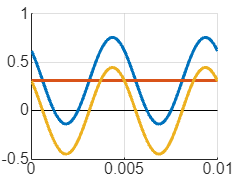

fig2				= figure;
ax2					= axes(fig2); hold on; grid on;
ax2.FontSize		= 8;
ax2.XLim			= [t(1) t(end)];

plot(ax2,ax2.XLim,[0 0],"k")

ax2.ColorOrderIndex		= 1;

plot(ax2,t,Pinst,LineWidth=1.5);
plot(ax2,t,Pave,LineWidth=1.5);
plot(ax2,t,Palt,LineWidth=1.5);